clc;
clear;

data = 'free_space';
contact = 'no_contact';
test_folder = 'test';
rnn = 'lstm';
network = '_seal_pred_filtered_torque_colon_9_26.csv';
% network = '_seal_pred_filtered_torque_si_3_15.csv';

%loss = 0;
loss = [0,0,0,0];

%for file = 0:3
file = 0;
exp = ['exp',num2str(file)];

exp = 'test_shaft_4_trocar';


%     joint_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/joints/'];
%     torque_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/', rnn, network];
    

%       joint_path = ['../../../Downloads/trial_pipeline_1', '/joints/'];
%       jacobian_path = ['../../../Downloads/trial_pipeline_1', '/jacobian/'];
%       torque_path = ['../../../Downloads/trial_pipeline_1', '/TO_free_comp_model_pred.csv'];
%       corr_tq_path = ['../../../Downloads/trial_pipeline_1', '/filtered_corrected_torque_prediction.csv'];

      
      joint_path = ['../../simon_trocar_mar_6/',exp, '/joints/'];
      jacobian_path = ['../../simon_trocar_mar_6/', exp, '/jacobian/'];
      torque_path = ['../../simon_trocar_mar_6/', exp, '/TO_cont_model_pred.csv'];
      corr_tq_path = ['../../simon_trocar_mar_6/', exp, '/filtered_corrected_torque_prediction_2min.csv'];

joint_data = readmatrix([joint_path, 'interpolated_all_joints_CUT.csv']);
jacobian_data = readmatrix([jacobian_path, 'interpolated_all_jacobian_CUT.csv']);
torque_data = readmatrix(torque_path);
corr_tq = readmatrix(corr_tq_path);

jacobian = jacobian_data(:, 2:37).';
jacobian = reshape(jacobian,[6,6,length(jacobian)]);
jacobian = permute(jacobian, [2 1 3]);

jacobian(:,:,1)

ans =    -0.0000   -0.0000    0.4505   -0.0000    0.0387   -0.1184
    0.0000    0.0000    0.5755   -0.0000    0.0923    0.0706
   -0.0000    0.0000   -0.6826   -0.0000    0.1034   -0.0187
    0.0000   -0.8346         0    0.4505   -0.8513   -0.4363
   -1.0000   -0.0000         0    0.5755    0.5073   -0.8263
    0.0000   -0.5509         0   -0.6826   -0.1342   -0.3562



corr_pred_torque = corr_tq(:,2:7).';
fs_pred_torque = torque_data(1:length(corr_pred_torque),1:6).';

% fs_pred_torque = fs_pred_torque(:, 1:length(fs_pred_torque)/2);
measured_torque = joint_data(1:length(corr_pred_torque),14:19).';
jacobian = jacobian(:,:,1:length(corr_pred_torque));

fs_diff = measured_torque  - corr_pred_torque;
fs_diff_wo_corr = measured_torque - fs_pred_torque;
fs_force = zeros(6,length(fs_pred_torque));

angle = pi/2+pi/20;
Ra = [cos(angle) -sin(angle) 0; sin(angle) cos(angle) 0; 0 0 1]

Ra =    -0.1564   -0.9877         0
    0.9877   -0.1564         0
         0         0    1.0000


Rz = [-1.0000 0 0; 0 -0.7071 -0.7071; 0 -0.7071 0.7071]

Rz =    -1.0000         0         0
         0   -0.7071   -0.7071
         0   -0.7071    0.7071


% Rz = [cos(angle) 0 sin(angle); 0 1 0; -sin(angle) 0 cos(angle)]  % Ry actually
% Rz = [1 0 0; 0 cos(angle) -sin(angle);0 sin(angle) cos(angle)]  % Rx actually
det(Rz)

ans = 1.0000

another_angle = -pi/4-pi/20;
rotation = [cos(another_angle) -sin(another_angle) 0; sin(another_angle) cos(another_angle) 0; 0 0 1]

rotation =     0.5878    0.8090         0
   -0.8090    0.5878         0
         0         0    1.0000



for i = 1:length(fs_pred_torque)
    fs_force(:,i) = inv(jacobian(:,:,i).') * (fs_diff(:,i));
    fs_force_wo_corr(:,i) = inv(jacobian(:,:,i).') * (fs_diff_wo_corr(:,i));
    fs_force(1:3, i) = rotation * fs_force(1:3, i);
    fs_force_wo_corr(1:3, i) = rotation * fs_force_wo_corr(1:3, i);
end

fs_force = fs_force.';
fs_force_wo_corr = fs_force_wo_corr.';


real_force_path = ['../../simon_trocar_mar_6/',exp, '/sensor/'];
% real_force_path = ['dvrk-si-3-15/csv_si/', 'sensor/'];
real_force_data = readmatrix([real_force_path, 'interpolated_all_sensor_CUT.csv']);
real_force = real_force_data(1:length(fs_pred_torque),2:7);



windowSize = 30; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

fs_force_filt = filter(b,a,fs_force);

fs_force_unfilt = fs_force;

% fs_force = filter(b,a,fs_force);

loss_x = mean(sqrt(mean( (fs_force(:,1) - real_force(:,1)).^2 )));
loss_y = mean(sqrt(mean( (fs_force(:,2) - real_force(:,2)).^2 )));
loss_z = mean(sqrt(mean( (fs_force(:,3) - real_force(:,3)).^2 )));
loss_taux = mean(sqrt(mean( (fs_force(:,4) - real_force(:,4)).^2 )));
loss_tauy = mean(sqrt(mean( (fs_force(:,5) - real_force(:,5)).^2 )));
loss_tauz = mean(sqrt(mean( (fs_force(:,6) - real_force(:,6)).^2 )));

loss_x_wo_corr = mean(sqrt(mean( (fs_force_wo_corr(:,1) - real_force(:,1)).^2 )));
loss_y_wo_corr = mean(sqrt(mean( (fs_force_wo_corr(:,2) - real_force(:,2)).^2 )));
loss_z_wo_corr = mean(sqrt(mean( (fs_force_wo_corr(:,3) - real_force(:,3)).^2 )));

[minSix, maxSix] = bounds(fs_force(:,1));
boundX = abs(maxSix - minSix)

boundX = 33.4022

[minSiy, maxSiy] = bounds(fs_force(:,2));
boundY = abs(minSiy - maxSiy)

boundY = 38.1529

[minSiz, maxSiz] = bounds(fs_force(:,3));
boundZ = abs(maxSiz - minSiz)

boundZ = 35.2459

loss_x_nrmse = loss_x/boundX

loss_x_nrmse = 0.0629

loss_y_nrmse = loss_y/boundY

loss_y_nrmse = 0.0678

loss_z_nrmse = loss_z/boundZ

loss_z_nrmse = 0.0712

loss_x_wo_corr_nrmse = loss_x_wo_corr/boundX

loss_x_wo_corr_nrmse = 0.0817

loss_y_wo_corr_nrmse = loss_y_wo_corr/boundY

loss_y_wo_corr_nrmse = 0.0915

loss_z_wo_corr_nrmse = loss_z_wo_corr/boundZ

loss_z_wo_corr_nrmse = 0.0939

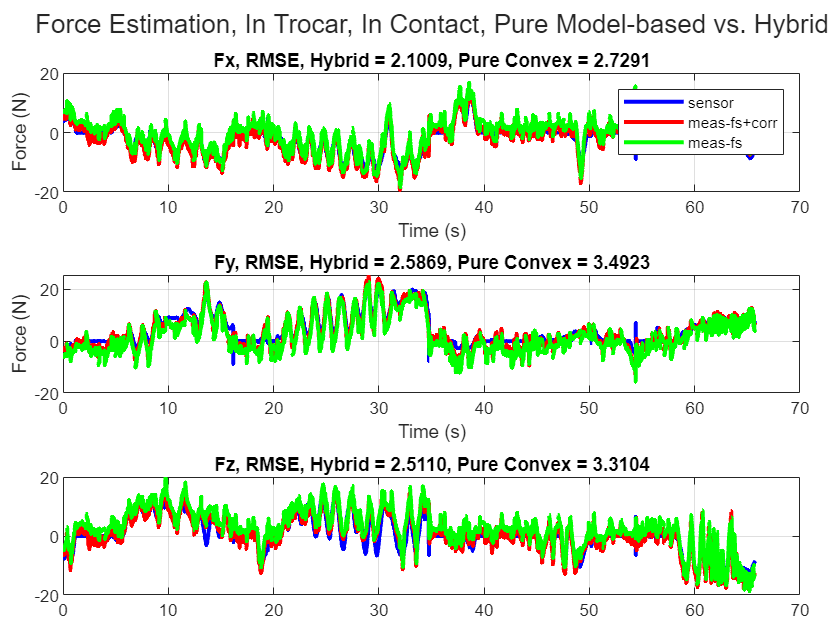



figure()
tcl = tiledlayout(3,1, 'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('Force Estimation, In Trocar, In Contact, Pure Model-based vs. Hybrid'))



nexttile
plot(joint_data(1:length(real_force)), real_force(:,1), 'b', 'LineWidth', 2)
hold on
title(sprintf('Fx, RMSE, Hybrid = %.4f, Pure Convex = %.4f', loss_x, loss_x_wo_corr))
plot(joint_data(10:length(real_force)-10), fs_force(10:length(real_force)-10,1), 'r', 'LineWidth', 2)
plot(joint_data(10:length(real_force)-10), fs_force_wo_corr(10:length(real_force)-10,1), 'g', 'LineWidth', 2)
xlabel('Time (s)')
ylabel('Force (N)')
grid on

legend('sensor', 'meas-fs+corr', 'meas-fs','Location', 'northeast')

hold off

nexttile
plot(joint_data(6:length(real_force)), real_force(6:length(real_force),2), 'b', 'LineWidth', 2)
hold on
title(sprintf('Fy, RMSE, Hybrid = %.4f, Pure Convex = %.4f', loss_y, loss_y_wo_corr))
plot(joint_data(6:length(real_force)-0), fs_force(6:length(real_force)-0,2), 'r', 'LineWidth', 2)
plot(joint_data(6:length(real_force)-0), fs_force_wo_corr(6:length(real_force)-0,2), 'g', 'LineWidth', 2)
xlabel('Time (s)')
ylabel('Force (N)')
grid on
hold off

nexttile
plot(joint_data(1:length(real_force)), real_force(:,3), 'b', 'LineWidth', 2)
hold on
title(sprintf('Fz, RMSE, Hybrid = %.4f, Pure Convex = %.4f', loss_z,  loss_z_wo_corr))
plot(joint_data(10:length(real_force)-10), fs_force(10:length(real_force)-10,3), 'r', 'LineWidth', 2)
plot(joint_data(10:length(real_force)-10), fs_force_wo_corr(10:length(real_force)-10,3), 'g', 'LineWidth', 2)
grid on


hold off